# Kinematics in Action: Projectile Motion

In this script, we will explore the components relating to projectile motion and how certain equations and graphs represent kinematic relationships.

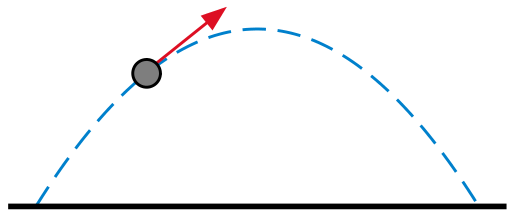

**Before you get Started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB. Part of this script include Simscape simulations, no prior knowledge is assumed here, but you might want to consider taking [Simscape Onramp](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape) as well.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

### X and Y Components of Projectile Motion and the Effects of Gravity

Projectile motion is a term that is used to describe the motion of an object that is launched into the air. 

When we launch an object, we can see that the object will curve through the air until it makes contact with another object such as a floor or wall.

  **Try.  **Check out what a typical projectile motion path looks like!

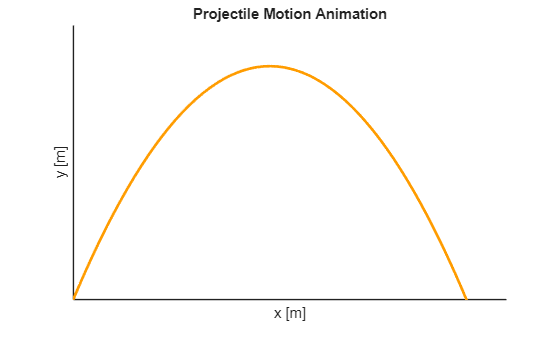

 

% define initial values
initialVelocity = 20; % m / s
initialAngle = 45; % degrees
gravity = 9.8; % m/s^2
t = 0:0.05:3.0; % s

x = (initialVelocity * cosd(initialAngle)) * t; % m
y = (initialVelocity * sind(initialAngle)) * t - 0.5 * gravity .* t.^2; % m

% plot description
clf;
title('Projectile Motion Animation')
xlabel('x [m]')
ylabel('y [m]')
grid on
xlim([0, 45]);
ylim([0, 12]);

% hide the axis values (not important)
% just want the user to see what a projectile motion path looks like
set(gca, 'XTick', [], 'YTick', [])

h = animatedline('Color', '[1.0, 0.61, 0]', 'LineWidth', 2);

% animate the plot
for i = 1:length(t)
    addpoints(h, x(i), y(i));
    drawnow;
    pause (0.02);
end

When working with 2D kinematics, we are only concerned with the 2D motion of the object, meaning that we only want to focus on the x and y components.

These components are completely independent of each other, meaning that we can analyze each component separately without worrying about the other one:

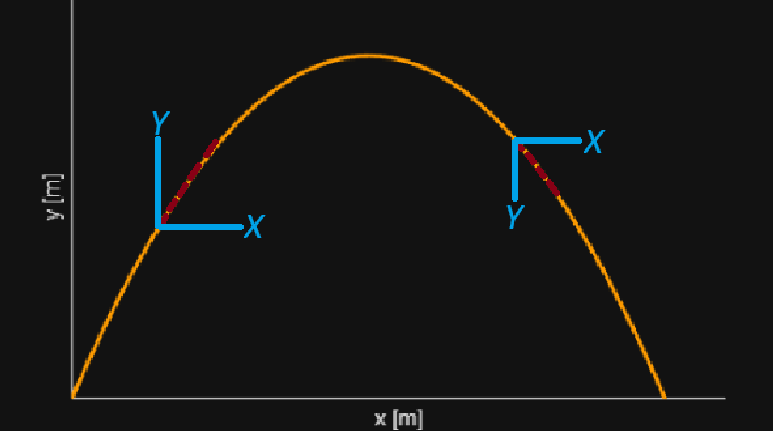

**Why does the object curve downwards?**

Under projectile motion, we neglect air resistance and therefore the only force that will be acting on the object is due to the downwards acceleration of gravity, which is given a value of:

                    
$$\mathit{\mathbf{g}}=9\ldotp 8\;\frac{\mathit{\mathbf{m}}}{{\mathit{\mathbf{s}}}^2 }$$


This means that there is a constant force pulling down on the object, dragging it downwards towards the floor, and this explains the trajection of projectile motion.

 **Exercise 1. **What component(s) are affected by gravity?

checkExercise1("X");


 

function checkExercise1(component)
    if strcmp(component, "X")
        warning("If gravity, as previously stated, is acting in the downwards direction, are you sure that is the x-component?")
    elseif strcmp(component, "Y")
        disp("Good job! You got the component right.")
        disp("This is simply due to the fact that gravity only acts in the vertical direction, which will cause the object to accelerate downwards.")
    elseif strcmp(component, "Both")
        warning("Gravity is only acting in one direction.")
    else
        warning("Select a component")
    end
end

### Modeling Motion Using Kinematic Equations

Hello this is my edit

### Signs, Conventions, and Graphing

When we choose signs for a projectile in motion, we typically choose the positive y-direction to be upwards and the positive x-direction to be rightwards. However, as long as we stay consistent, this choice is arbitrary. For example, if we choose left to be positive and receive a negative x-velocity, it means the projectile is moving to the right. 

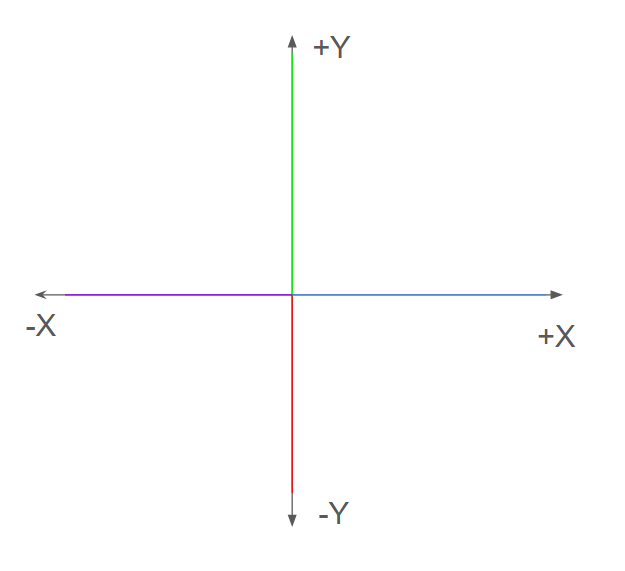

A typical coordinate grid for physics problems.

You may have seen one kinetic equation notated this way:


$$v_y =v_0 -\textrm{gt}$$


As opposed to its previous notation using a positive time-dependent term:


$$v_f =v_0 +\textrm{at}$$


The reason for this is conventions! By convention g, our term for gravity, is assigned to be negative because we typically take the negative y-direction to be downwards. 

 **Exercise 3. **When graphing projectile motion of a thrown object, we can separate the graphs for x-position over time and y-position over time respectively because there is a notable difference between the two. Can you identify it?

response = "acceleration";
if response == "acceleration"
    disp("Correct! Only the y-component has acceleration due to the force of gravity!");
else
    warning("Incorrect. Remember that the x-component is independent of gravity.");
end

Correct! Only the y-component has acceleration due to the force of gravity!


  **Try.** Here's an interactive where you can see this difference more clearly! Notice how the y-position over time is represented by a parabola to demonstrate the changing velocity due to acceleration. On the other hand, the x-position over time maintains a constant slope due to a lack of external acceleration. 

launchSpeed =33;
launchAngle =65;
component = "y";
graphResolution = 3; % Lower is more detailed
if component == "y"
    totalPositions = graphResolution*ceil(2*(launchSpeed*sind(launchAngle)/9.81));
    positions = zeros(totalPositions+1,1);
    for i = 0:1:totalPositions
        positions(i+1) = (launchSpeed * sind(launchAngle)) * (i/graphResolution) + (0.5*-9.81*(i/graphResolution)^2); % Calculate positions based on launch parameters
    end
    times = 0:1/graphResolution:totalPositions/graphResolution;
    plot(times,positions);
    title('Y-Position as a Function of Time');
    xlabel('Time (seconds)');
    ylabel('Y-Position (meters)');
    xlim([0.00 10.50]);
    xticks(0:1:10);
    ylim([0.00 150.00]);
    yticks(0:10:150);
else
    totalPositions = floor(graphResolution*(2*(launchSpeed*sind(launchAngle)/9.81)))+1;
    positions = zeros(totalPositions+1,1);
    for i = 0:1:totalPositions
        positions(i+1) = (launchSpeed * cosd(launchAngle)) * (i/graphResolution); % Calculate positions based on launch parameters
    end
    times = 0:1/graphResolution:totalPositions/graphResolution;
    plot(times,positions);
    title('X-Position as a Function of Time');
    xlabel('Time (seconds)');
    ylabel('X-Position (meters)');
    xlim([0.00 8.00]);
    ylim([0.00 290.00]);
end

disableDefaultInteractivity(gca);
grid on

x-velocity and x-acceleration over time aren't very necessary graphs seeing as x-velocity is constant, and thus a horizontal line. Similarly, seeing as there is no x-component of acceleration, the x-acceleration over time graph would be a horizontal line at y = 0. 

We can, however, graph the y-velocity over time. This can be done by simply using our starting y-velocity as our y-intercept and using our gravitational acceleration of 9.81 meters per second downwards as our slope:


$$v_f =v_0 -\left(9\ldotp 81\right)t$$


This should look familiar because we're directly using one of our kinematic equations to graph it. 


$$v_f =v_0 -\left(9\ldotp 81\right)t$$


### How to Relate Position, Velocity, and Acceleration

### Further Exploration

### Conclusion